csv = csvread('1.csv');
a = csv(:,1);
cl = csv(:,2);
cd = csv(:,3);
cdp = csv(:,4);
cm = csv(:,5);
topxtr = csv(:,6);
botxtr = csv(:,7);
topitr = csv(:,8);
botitr = csv(:,9);

hold on;

[cl_s, a_cl_s] = resample(cl, a, 10, 'spline');
plot(a_cl_s, cl_s);
[cd_s, a_cd_s] = resample(cd, a, 10, 'spline');
plot(a_cd_s, cd_s);

% good values: 0.3 0.66 0.3 40
% 0.3 0.66 0.10 40
pass = 0.3333;
stop = 0.6666;
ripple = 0.125;
atten = 40;

firlpf = designfilt('lowpassfir', 'PassbandFrequency', pass, 'StopbandFrequency', stop, ...
'PassbandRipple', ripple, 'StopbandAttenuation', atten, 'DesignMethod', 'equiripple', ...
'SampleRate', 1/(a_cl_s(2)-a_cl_s(1)) ...
);
class(firlpf)

ans = 'digitalFilter'

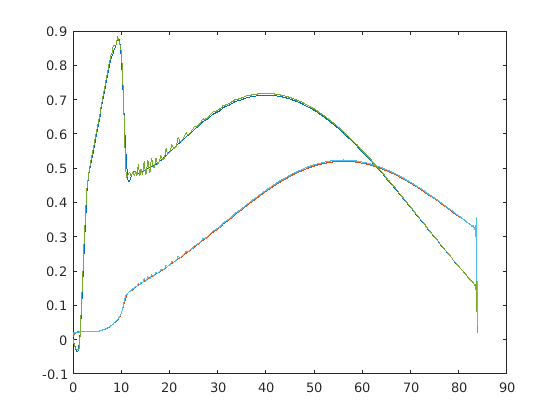




[A, B, C, D]=ss(firlpf);
firlpf_ss = ss(A, B, C, D, 1/firlpf.SampleRate);

hold off;


stepLast = step(firlpf_ss,0:0.1:20);
stepLast(end)

ans = 1.0068

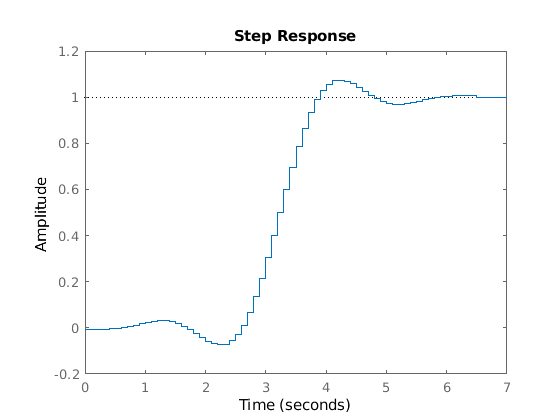

firlpf_ss = firlpf_ss * 1/stepLast(end);


step(firlpf_ss);

bode(firlpf_ss);

firlpf_ss = firlpf_ss * 1/stepLast(end);

[fir_out_cl, fir_out_cl_a] = lsim(firlpf_ss, cl_s, a_cl_s);
[fir_out_cd, fir_out_cd_a] = lsim(firlpf_ss, cd_s, a_cd_s);
delay=mean(grpdelay(firlpf));
a_cd_s = a_cd_s(1:end-delay);

a_cl_s = a_cl_s(1:end-delay);

cd_s = cd_s(1:end-delay);

cl_s = cl_s(1:end-delay);


fir_out_cl(1:delay) = [];

fir_out_cd(1:delay) = [];

fir_out_cl_a(1:delay) = [];

fir_out_cd_a(1:delay) = [];

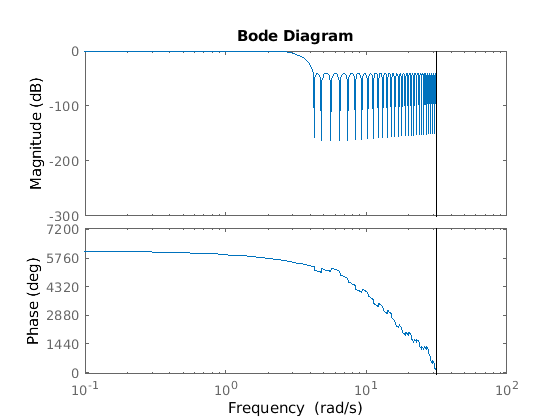


fir_out_cl_a = fir_out_cl_a - fir_out_cl_a(1);
fir_out_cd_a = fir_out_cd_a - fir_out_cd_a(1);


hold off;

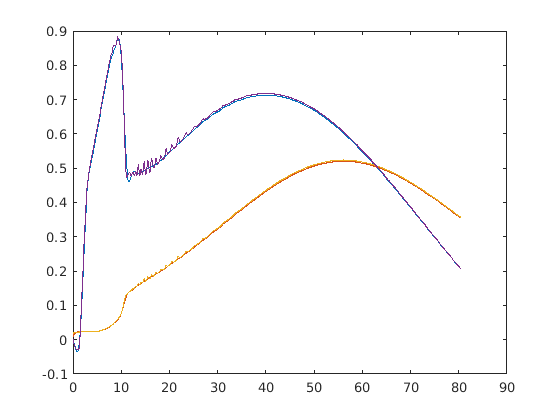

plot(fir_out_cl_a, fir_out_cl);
hold on;
plot(fir_out_cd_a, fir_out_cd);
plot(a_cd_s, cd_s);
plot(a_cl_s, cl_s);

csvwrite("output_filt_cl.csv", [fir_out_cl_a fir_out_cl]);
csvwrite("output_filt_cd.csv", [fir_out_cd_a fir_out_cd]);


 %alpha    CL        CD       CDp       CM     Top_Xtr  Bot_Xtr  Top_Itr  Bot_Itr